% readTimeDomainResults  Reads in results from a single simulation
%
close all
clear all
clc

## User-defined input

folderF1 = 'E:\DecayResults\Forces\1643-20230410075129\Forces_1';
folderF2 = 'E:\DecayResults\Forces\1643-20230410075129\Forces_2';
folderF3 = 'E:\DecayResults\Forces\1643-20230410075129\Forces_3';

folderM1 = 'E:\DecayResults\Moments\1643-20230410075132\Moments_1';
folderM2 = 'E:\DecayResults\Moments\1643-20230410075132\Moments_2';
folderM3 = 'E:\DecayResults\Moments\1643-20230410075132\Moments_3';

prefix = 'sima';
SemiBody = 2; % typically 1
numForChan = 116; % this is the number of channels in the force results ...123 original
% storage. You can find this in the key_sima_elmfor.txt file.


## F1 Output

%==========================================================================
%%READ SIMULATION OUTPUT
% Read the SIMO results text file to get the channel names and number
% of steps

[nchan, nts, dt, chanNames] = readSIMO_resultstext([folderF1 '\results.txt']);
% Read the binary file
AAF1 = read_simoresults([folderF1 '\results.tda'],nts);

 ... Binary file read: E:\DecayResults\Forces\1643-20230410075129\Forces_1\results.tda


sizeAAF1 = size(AAF1);
if (sizeAAF1(1)<nts || nts<1); disp('Unable to read SIMO results'); return; end;
% Determine which channels to read for the platform motions, wave
% elevation
[semiMotionsF1, semiWaveF1] = getchannelNumbers(chanNames,SemiBody);
if (semiMotionsF1(1)<1 || semiWaveF1<1); disp('Unable to read SIMO results'); return; end;


%discard transient
transF1=350; %s
AAF1(1:(transF1/dt),:)=[];
time_SIMO_F1 = AAF1(:,2);
% summarize data in matrix
SemiMotionsF1 = AAF1(:,semiMotionsF1);
SemiwaveF1 = AAF1(:,semiWaveF1);

SemiXgF1=SemiMotionsF1(:,1);
SemiYgF1=SemiMotionsF1(:,2);
SemiZF1=SemiMotionsF1(:,3);
[pks,locs] = findpeaks(SemiXgF1,time_SIMO_F1);
periodXF1 = max(diff(locs));





## F2 Output

%==========================================================================
%%READ SIMULATION OUTPUT
% Read the SIMO results text file to get the channel names and number
% of steps

[nchan, nts, dt, chanNames] = readSIMO_resultstext([folderF2 '\results.txt']);
% Read the binary file
AAF2 = read_simoresults([folderF2 '\results.tda'],nts);

 ... Binary file read: E:\DecayResults\Forces\1643-20230410075129\Forces_2\results.tda


sizeAAF2 = size(AAF2);
if (sizeAAF2(1)<nts || nts<1); disp('Unable to read SIMO results'); return; end;
% Determine which channels to read for the platform motions, wave
% elevation
[semiMotionsF2, semiWaveF2] = getchannelNumbers(chanNames,SemiBody);
if (semiMotionsF2(1)<1 || semiWaveF2<1); disp('Unable to read SIMO results'); return; end;


%discard transient
transF2=350; %s
AAF2(1:(transF2/dt),:)=[];
time_SIMO_F2 = AAF2(:,2);
% summarize data in matrix
SemiMotionsF2 = AAF2(:,semiMotionsF2);
SemiwaveF2 = AAF2(:,semiWaveF2);

SemiXgF2=SemiMotionsF2(:,1);
SemiYgF2=SemiMotionsF2(:,2);
SemiZF2=SemiMotionsF2(:,3);

[pks,locs] = findpeaks(SemiYgF2,time_SIMO_F2);
periodYF2 = max(diff(locs))

periodYF2 = 19.7000

##  F3 Output

%==========================================================================
%%READ SIMULATION OUTPUT
% Read the SIMO results text file to get the channel names and number
% of steps

[nchan, nts, dt, chanNames] = readSIMO_resultstext([folderF3 '\results.txt']);
% Read the binary file
AAF3 = read_simoresults([folderF3 '\results.tda'],nts);

 ... Binary file read: E:\DecayResults\Forces\1643-20230410075129\Forces_3\results.tda


sizeAAF3 = size(AAF3);
if (sizeAAF3(1)<nts || nts<1); disp('Unable to read SIMO results'); return; end;
% Determine which channels to read for the platform motions, wave
% elevation
[semiMotionsF3, semiWaveF3] = getchannelNumbers(chanNames,SemiBody);
if (semiMotionsF3(1)<1 || semiWaveF3<1); disp('Unable to read SIMO results'); return; end;


%discard transient
transF3=200; %s
AAF3(1:(transF3/dt),:)=[];
time_SIMO_F3 = AAF3(:,2);
% summarize data in matrix
SemiMotionsF3 = AAF3(:,semiMotionsF3);
SemiwaveF3 = AAF3(:,semiWaveF3);

SemiXgF3=SemiMotionsF3(:,1);
SemiYgF3=SemiMotionsF3(:,2);
SemiZF3=SemiMotionsF3(:,3);
[pks,locs] = findpeaks(SemiZF3(1:1500),time_SIMO_F3(1:1500));
periodZF3 = max(diff(locs))

periodZF3 = 18.3000

## M1 Output

%==========================================================================
%%READ SIMULATION OUTPUT
% Read the SIMO results text file to get the channel names and number
% of steps

[nchan, nts, dt, chanNames] = readSIMO_resultstext([folderM1 '\results.txt']);
% Read the binary file
AAM1 = read_simoresults([folderM1 '\results.tda'],nts);

 ... Binary file read: E:\DecayResults\Moments\1643-20230410075132\Moments_1\results.tda


sizeAAM1 = size(AAM1);
if (sizeAAM1(1)<nts || nts<1); disp('Unable to read SIMO results'); return; end;
% Determine which channels to read for the platform motions, wave
% elevation
[semiMotionsM1, semiWaveM1] = getchannelNumbers(chanNames,SemiBody);
if (semiMotionsM1(1)<1 || semiWaveM1<1); disp('Unable to read SIMO results'); return; end;


%discard transient
transM1=250; %s
AAM1(1:(transM1/dt),:)=[];
time_SIMO_M1 = AAM1(:,2);
% summarize data in matrix
SemiMotionsM1 = AAM1(:,semiMotionsM1);
SemiwaveM1 = AAM1(:,semiWaveM1);

SemiXgM1=SemiMotionsM1(:,4);
SemiYgM1=SemiMotionsM1(:,5);
SemiZM1=SemiMotionsM1(:,6);
[pks,locs] = findpeaks(SemiXgM1(1:2500),time_SIMO_M1(1:2500));
periodXM1 = max(diff(locs))

periodXM1 = 30.8000

## M2 Output

%==========================================================================
%%READ SIMULATION OUTPUT
% Read the SIMO results text file to get the channel names and number
% of steps

[nchan, nts, dt, chanNames] = readSIMO_resultstext([folderM2 '\results.txt']);
% Read the binary file
AAM2 = read_simoresults([folderM2 '\results.tda'],nts);

 ... Binary file read: E:\DecayResults\Moments\1643-20230410075132\Moments_2\results.tda


sizeAAM2 = size(AAM2);
if (sizeAAM2(1)<nts || nts<1); disp('Unable to read SIMO results'); return; end;
% Determine which channels to read for the platform motions, wave
% elevation
[semiMotionsM2, semiWaveM2] = getchannelNumbers(chanNames,SemiBody);
if (semiMotionsM2(1)<1 || semiWaveM2<1); disp('Unable to read SIMO results'); return; end;


%discard transient
transM2=250; %s
AAM2(1:(transM2/dt),:)=[];
time_SIMO_M2 = AAM2(:,2);
% summarize data in matrix
SemiMotionsM2 = AAM2(:,semiMotionsM2);
SemiwaveM2 = AAM2(:,semiWaveM2);

SemiXgM2=SemiMotionsM2(:,4);
SemiYgM2=SemiMotionsM2(:,5);
SemiZM2=SemiMotionsM2(:,6);
[pks,locs] = findpeaks(SemiYgM2(1:2000),time_SIMO_M2(1:2000));
periodYM2 = max(diff(locs))

periodYM2 = 33.3000

## M3 Output

%==========================================================================
%%READ SIMULATION OUTPUT
% Read the SIMO results text file to get the channel names and number
% of steps

[nchan, nts, dt, chanNames] = readSIMO_resultstext([folderM3 '\results.txt']);
% Read the binary file
AAM3 = read_simoresults([folderM3 '\results.tda'],nts);

 ... Binary file read: E:\DecayResults\Moments\1643-20230410075132\Moments_3\results.tda


sizeAAM3 = size(AAM3);
if (sizeAAM3(1)<nts || nts<1); disp('Unable to read SIMO results'); return; end;
% Determine which channels to read for the platform motions, wave
% elevation
[semiMotionsM3, semiWaveM3] = getchannelNumbers(chanNames,SemiBody);
if (semiMotionsM3(1)<1 || semiWaveM3<1); disp('Unable to read SIMO results'); return; end;


%discard transient
transM3=250; %s
AAM3(1:(transM3/dt),:)=[];
time_SIMO_M3 = AAM3(:,2);
% summarize data in matrix
SemiMotionsM3 = AAM3(:,semiMotionsM3);
SemiwaveM3 = AAM3(:,semiWaveM3);

SemiXgM3=SemiMotionsM3(:,4);
SemiYgM3=SemiMotionsM3(:,5);
SemiZgM3=SemiMotionsM3(:,6);

SemiZlM3=zeros(1,length(SemiZgM3));
for k=1:length(SemiZgM3)
    if SemiZgM3(k)>0
        SemiZlM3(k)=SemiZgM3(k)-270;
    end
    if SemiZgM3(k)<0
        SemiZlM3(k)=SemiZgM3(k)+90;
    end
end
[pks,locs] = findpeaks(SemiZlM3,time_SIMO_M3);
periodZM3 = max(diff(locs))

periodZM3 = 114.6000

## Plots

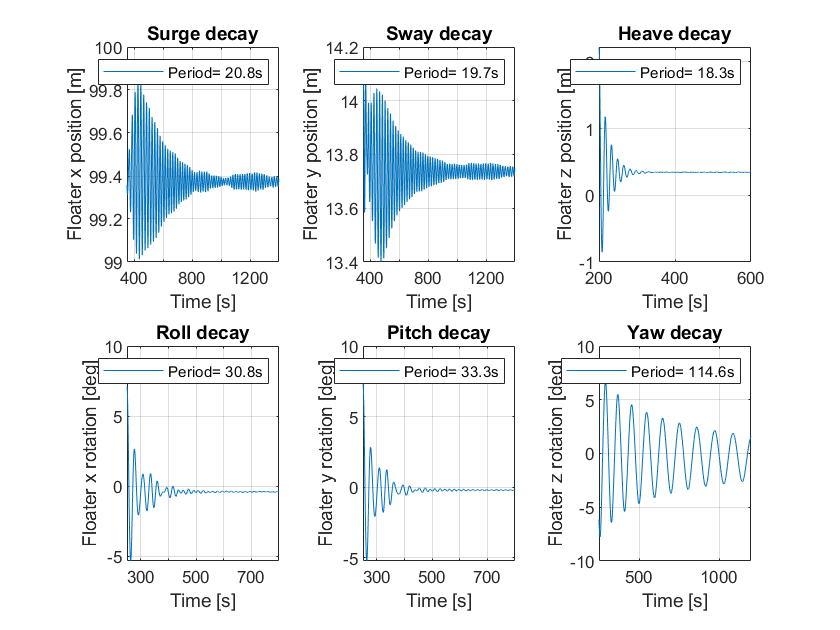

figure()
subplot(2,3,1)
legper=num2str(periodXF1);
leglab=['Period= ' legper 's'];

plot(time_SIMO_F1,SemiXgF1)
grid on
title('Surge decay')
xlabel('Time [s]')
ylabel('Floater x position [m]')
legend(leglab)

subplot(2,3,2)
legper=num2str(periodYF2 );
leglab=['Period= ' legper 's'];
plot(time_SIMO_F1,SemiYgF2)
grid on
title('Sway decay')
xlabel('Time [s]')
ylabel('Floater y position [m]')
legend(leglab)

subplot(2,3,3)
legper=num2str(periodZF3 );
leglab=['Period= ' legper 's'];
plot(time_SIMO_F3,SemiZF3)
grid on
title('Heave decay')
xlabel('Time [s]')
ylabel('Floater z position [m]')
legend(leglab)

subplot(2,3,4)
legper=num2str(periodXM1 );
leglab=['Period= ' legper 's'];

plot(time_SIMO_M1,SemiXgM1)
grid on
title('Roll decay')
xlabel('Time [s]')
ylabel('Floater x rotation [deg]')
legend(leglab)

subplot(2,3,5)
legper=num2str(periodYM2 );
leglab=['Period= ' legper 's'];

plot(time_SIMO_M1,SemiYgM2)
grid on
title('Pitch decay')
xlabel('Time [s]')
ylabel('Floater y rotation [deg]')
legend(leglab)

subplot(2,3,6)
legper=num2str(periodZM3 );
leglab=['Period= ' legper 's'];

plot(time_SIMO_M3,SemiZlM3)
grid on
title('Yaw decay')
xlabel('Time [s]')
ylabel('Floater z rotation [deg]')
legend(leglab)